Km = 50

Km = 50

T = 0.02

T = 0.0200

l = 0.90 %m

l = 0.9000

L = 0.115 %m

L = 0.1150

theta0 = 0

theta0 = 0

x0 = 1

x0 = 1

y0 = 0.8

y0 = 0.8000

Kx = 10 % définit en m.s-1.m-1 

Kx = 10

Ky = 10 % définit en m.s-1.m-1

Ky = 10


epsilon1 = -0.1; 
epsilon2 = -0.1; 

waypoints = [1 0.8; 1.8 0.8; 1.8 2.2 ;4 2.2 ; 1.8 2.2 ; 1.8 2.5 ;1 2.5;1.8 2.5; 1.8 0.8;1 0.8]

waypoints =     1.0000    0.8000
    1.8000    0.8000
    1.8000    2.2000
    4.0000    2.2000
    1.8000    2.2000
    1.8000    2.5000
    1.0000    2.5000
    1.8000    2.5000
    1.8000    0.8000
    1.0000    0.8000


timepoints = [0;5;10;15;20;25;30;35;40;45]

timepoints =      0
     5
    10
    15
    20
    25
    30
    35
    40
    45


n = size(timepoints,1)

n = 10

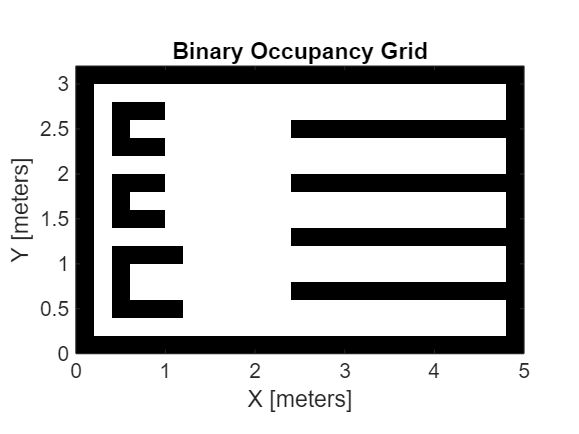

% Créer une carte 5x3 avec une résolution de 5 cellules/mètre
entrepot = binaryOccupancyMap(5, 3.2, 5);

addWall(entrepot, 2.5, 0.8, 5, 0.8);

addWall(entrepot, 2.5, 1.4, 5, 1.4);

addWall(entrepot, 2.5, 2, 5, 2);

addWall(entrepot, 2.5, 2.6, 5, 2.6);

addWall(entrepot, 0, 0, 5, 0);

addWall(entrepot, 0, 3.2, 5, 3.2);

addWall(entrepot, 0, 0, 0, 3.2);

addWall(entrepot, 5, 0, 5, 3.2);


addWall(entrepot, 0.6, 2.4, 1, 2.4);
addWall(entrepot, 0.6, 2.4, 0.6, 2.8);
addWall(entrepot, 0.6, 2.8, 1, 2.8);

addWall(entrepot, 0.6, 1.6, 1, 1.6);
addWall(entrepot, 0.6, 1.6, 0.6, 2);
addWall(entrepot, 0.6, 2, 1, 2);

addWall(entrepot, 0.6, 1.2, 1.2, 1.2);
addWall(entrepot, 0.6, 1.2, 0.6, 0.6);
addWall(entrepot, 0.6, 0.6, 1.2, 0.6);

% Afficher la carte
figure;
show(entrepot);


save('entrepot.mat','entrepot');

function addWall(map, startX, startY, endX, endY)
    % Ajoute un mur dans une binaryOccupancyMap en occupant chaque cellule traversée
    % map : binaryOccupancyMap
    % startX, startY : coordonnées du début du mur
    % endX, endY : coordonnées de fin du mur

    % Obtenir la résolution (cellules par mètre)
    res = map.Resolution;

    % Convertir en indices de grille (chaque cellule est espacée de 1/res mètres)
    startCell = round([startX, startY] * res);
    endCell = round([endX, endY] * res);

    % Générer les points entre startCell et endCell en remplissant chaque cellule
    if startCell(1) == endCell(1) % Mur vertical
        yCells = startCell(2):sign(endCell(2) - startCell(2)):endCell(2);
        xCells = repmat(startCell(1), size(yCells));
    elseif startCell(2) == endCell(2) % Mur horizontal
        xCells = startCell(1):sign(endCell(1) - startCell(1)):endCell(1);
        yCells = repmat(startCell(2), size(xCells));
    else
        error('Seuls les murs horizontaux et verticaux sont supportés.');
    end

    % Convertir en coordonnées réelles
    xReal = xCells / res;
    yReal = yCells / res;

    % Ajouter les cellules occupées à la carte
    setOccupancy(map, [xReal', yReal'], ones(length(xReal), 1));
end
